clear;  clc;

% ------------ fixed design data --------------------------------
lambda0   = 1e-6;                
thetaGoal = 5*pi/180;            
targetR2  = 0.99;               
dTheta    = 0.05;                

eta0 = 376.730313668;           
nH = 1.5;   nL = 1.4;            
dH = 100e-6;                    
dL =  90e-6;

% ------------ (1) search for |R²| ≥ 0.99 at θ = 5° --------------
pair = 0;
while true
    pair = pair + 1;
    [n,d] = buildStack(nH,nL,dH,dL,2*pair);
    R2now = reflectanceTM(n,d,thetaGoal,lambda0,eta0);
    if R2now >= targetR2
        optLayers = numel(n)-2;          % drop two air half-spaces
        fprintf('|R²| ≥ %.2f at 5° with %d layers (= %d HL pairs)\n',...
                targetR2,optLayers,pair);
        break
    end
    if pair > 500
        error('Did not reach |R²| ≥ 0.99 with up to 1000 layers.');
    end
end

|R²| ≥ 0.99 at 5° with 90 layers (= 45 HL pairs)


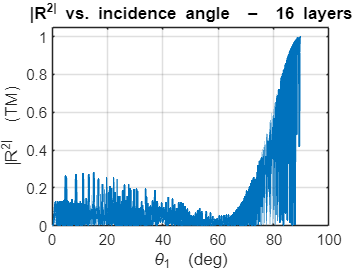

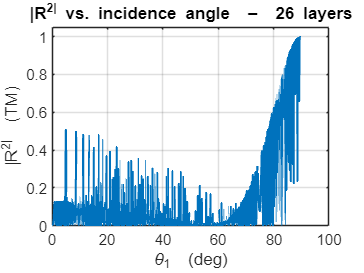

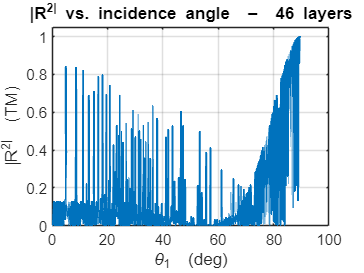

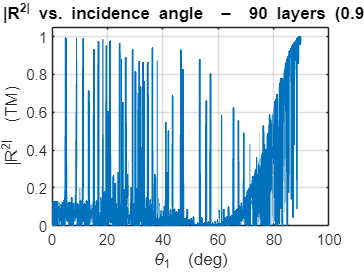


% ------------ (2) θ-sweep for all requested stacks ---------------
thetaDeg = 0:dTheta:89.9;
thetaRad = deg2rad(thetaDeg);

layerSets = [16 26 46 optLayers];
labels    = {'16 layers','26 layers','46 layers',...
             sprintf('%d layers (0.99)',optLayers)};

for k = 1:numel(layerSets)
    N = layerSets(k);
    [n,d] = buildStack(nH,nL,dH,dL,N);

    Rtheta = arrayfun(@(th) reflectanceTM(n,d,th,lambda0,eta0),thetaRad);

    figure('Color','w');
    plot(thetaDeg,Rtheta,'LineWidth',1.2);
    ylim([0 1.05]);  grid on;
    xlabel('\theta_1  (deg)');  ylabel('|R^2|  (TM)');
    title(['|R^2| vs. incidence angle  –  ' labels{k}]);
end


%functions

function [n,d] = buildStack(nH,nL,dH,dL,Nlayers)
% air | HLHL… (Nlayers) | air
seqN = repmat([nH nL],1,ceil(Nlayers/2));
seqD = repmat([dH dL],1,ceil(Nlayers/2));
n = [1 seqN(1:Nlayers) 1];
d = [0 seqD(1:Nlayers) 0];
end
% ---------------------------------------------------------------------

function R2 = reflectanceTM(n,d,theta,lambda,eta0)
% |R²| = abs( r^2 ) for TM polarisation (transfer-matrix method)
k0 = 2*pi/lambda;
kx = k0*n(1)*sin(theta);
kz = sqrt((k0*n).^2 - kx.^2);
ct = kz./(k0*n);

M = eye(2);
for i = 1:numel(n)-1
    eta1 = eta0/n(i);   eta2 = eta0/n(i+1);
    r = (eta2*ct(i+1) - eta1*ct(i)) / ...
        (eta2*ct(i+1) + eta1*ct(i));
    t = 2*eta2*ct(i) / ...
        (eta2*ct(i+1) + eta1*ct(i));
    T = (1/t)*[1 r; r 1];
    if d(i+1) > 0
        P = [exp( 1j*kz(i+1)*d(i+1)) 0;
             0                      exp(-1j*kz(i+1)*d(i+1))];
        M = M*T*P;
    else
        M = M*T;
    end
end
rGlob = M(2,1)/M(1,1);
R2 = abs(rGlob.^2);
end
% ---------------------------------------------------------------------